% Load the data file
load('data_4.mat');

% Define window size and overlap
win_size = 30*Fs;
overlap = 29*Fs;

% Define frequency range for spectrogram
F_range = 0.1:0.1:32; % in Hz

% Compute spectrogram
[S, F, T, P] = spectrogram(signal, win_size, overlap, F_range, Fs);

% Compute spectral entropy
norm_P = P./sum(P, 1);
Nf = size(P, 1);
spec_E = -sum(norm_P.*log2(norm_P),1)./log2(Nf);

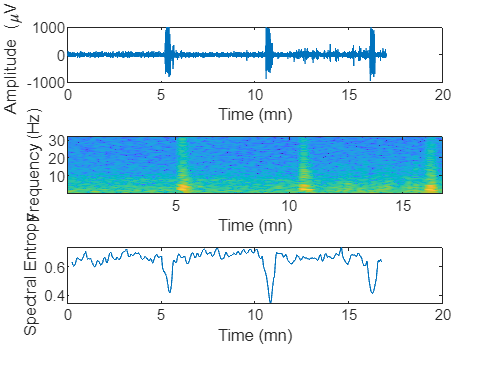

% Plot the RAW EEG signal
subplot(3,1,1);
plot(t, signal);
ylabel('Amplitude (\muV)');
xlabel('Time (mn)');
ylim([-1000 1000]);

% Plot the spectrogram
subplot(3,1,2);
imagesc(T/60,F,log10(P),[-4 6]);
axis xy;
ylabel('Frequency (Hz)');
xlabel('Time (mn)');

% Plot the spectral entropy
subplot(3,1,3);
plot(T/60, spec_E);
ylabel('Spectral Entropy');
xlabel('Time (mn)');

ictal_t0 = 60*5.25*Fs;
ictal_t1 = ictal_t0 + length(t1) - 1;
signal1 = signal(ictal_t0:ictal_t1);
signal2 = signal(1:length(t1));

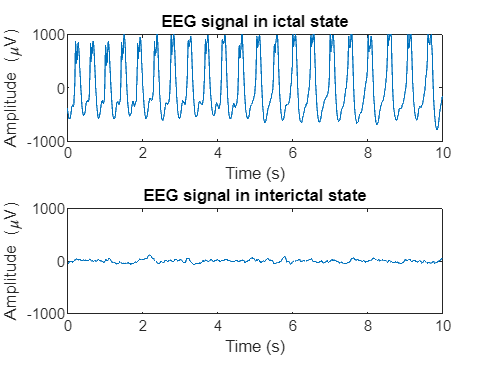

% Plot the raw EEG signals for both segments
figure;
subplot(2, 1, 1);
plot(t1, signal1);
title('EEG signal in ictal state');
xlabel('Time (s)');
ylabel('Amplitude (\muV)');
ylim([-1000, 1000]);

subplot(2, 1, 2);
plot(t1, signal2);
title('EEG signal in interictal state');
xlabel('Time (s)');
ylabel('Amplitude (\muV)');
ylim([-1000, 1000]);

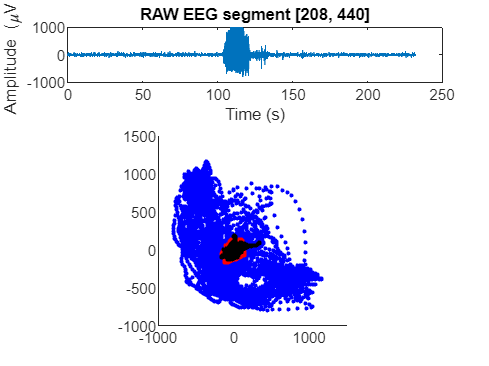

signal3 = signal(208*Fs:440*Fs);

figure;
subplot(3, 1, 1);
plot(t2, signal3);
title('RAW EEG segment [208, 440]');
xlabel('Time (s)');
ylabel('Amplitude (\muV)');
ylim([-1000, 1000]);

subplot(3, 1, [2 3]);
hold on;
plot(signal3(100*Fs:132*Fs), signal3(100*Fs+67:132*Fs+67), 'b.');
plot(signal3(1:90*Fs), signal3(1+67:90*Fs+67), 'r.');
plot(signal3(142*Fs:length(signal3)-67), signal3(142*Fs+67:length(signal3)), 'r.');
plot(signal3(90*Fs:100*Fs), signal3(90*Fs+67:100*Fs+67), 'k.');
plot(signal3(132*Fs:142*Fs), signal3(132*Fs+67:142*Fs+67), 'k.');
axis equal;
xlim([-1000, 1500])
ylim([-1000, 1500]);